# **MATLAB Workshop - 07/28/2017**

**Márcio Duarte Albasini Mourão**

**Materials for this session can be found here: **[https://marcio-mourao.github.io](https://marcio-mourao.github.io)** - Part II**

## MATLAB (MATrix LABoratory) is a high-level programming language and interactive environment for algorithm development, data visualization, data analysis, and numeric computation. Core strengths of the system include rapid development, powerful built-in functionality and extensive application-specific functionality provided by both official toolboxes and user-contributed code.

## MATLAB contains several different parts:

- **Desktop Tools and Development Environment** **-** This part of MATLAB is the set of tools and facilities that help you use and become more productive with MATLAB functions and files. Many of these tools are graphical user interfaces. It includes: the MATLAB desktop and Command Window, an editor and debugger, a code analyzer, and browsers for viewing help, the workspace, and folders.

- **Mathematical Function Library -** This library is a vast collection of computational algorithms ranging from elementary functions, like sum, sine, cosine, and complex arithmetic, to more sophisticated functions like matrix inverse, matrix eigenvalues, and fast Fourier transforms.

- **The Language -** The MATLAB language is a high-level matrix/array language with control flow statements, functions, data structures, input/output, and object-oriented programming features. It allows both "programming in the small" to rapidly create quick programs you do not intend to reuse. You can also do "programming in the large" to create complex application programs intended for reuse.

- **Graphics -** MATLAB has extensive facilities for displaying vectors and matrices as graphs, as well as annotating and printing these graphs. It includes high-level functions for two-dimensional and three-dimensional data visualization, image processing, animation, and presentation graphics. It also includes low-level functions that allow you to fully customize the appearance of graphics as well as to build complete graphical user interfaces on your MATLAB applications.

- **External Interfaces -** The external interfaces library allows you to write C and Fortran programs that interact with MATLAB. It includes facilities for calling routines from MATLAB (dynamic linking), for calling MATLAB as a computational engine, and for reading and writing MAT-files.

# **References**

## **A MATLAB Tutorial -  **[https://people.math.osu.edu/overman.2/matlab.pdf](https://people.math.osu.edu/overman.2/matlab.pdf)

## **        Ed Overman, Department of Mathematics, The Ohio State University**

## **Introduction to MATLAB for engineering students - **[http://www.mccormick.northwestern.edu/docs/efirst/matlab.pdf](http://www.mccormick.northwestern.edu/docs/efirst/matlab.pdf)

## **       David Houcque, Northwestern University**

## Some exercises - [**http://www.facstaff.bucknell.edu/maneval/help211/exercises.html**](http://www.facstaff.bucknell.edu/maneval/help211/exercises.html)

# **Summary**

- **Quick revision: Vectors and Matrices**

- **Strings**

- **Cell arrays**

- **Structures**

- **Tables**

- **Control flow and operators**

- **Visualization of data**

# **Definitions: Matrices and Vectors**

- `The most basic MATLAB data structure is the matrix: a two-dimensional, rectangular structure capable of storing multiple elements of data in an easily accessible format.`

- `The elements of a matrix must all be of the same data type (numeric, character, logical etc.), but here we will focus on numeric matrices.`

- `MATLAB uses two-dimensional matrices to store single elements and linear series of elements as well. In these cases, the dimensions are 1-by-1 and 1-by-N (or N-by-1) respectively. For numeric data, special meaning is sometimes attached to 1-by-1 matrices, which are scalars, and to matrices with only one row or column, which are vectors.`

- `MATLAB also supports data structures that have more than two dimensions. These data structures are referred to as multidimensional arrays, and indeed the matrix is really a special case of an n-dimension array, with n=2.`

# **MATLAB data types**

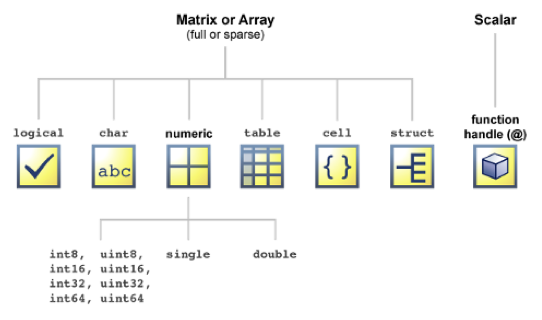

[http://www.mathworks.com/help/matlab/matlab_prog/fundamental-matlab-classes.html](http://www.mathworks.com/help/matlab/matlab_prog/fundamental-matlab-classes.html)

# **Quick revision: V****ectors**

clear

x=[3 2 3 7 5]

x=1:2:10

x=zeros(5,1)

x=linspace(1,5,10)

x=logspace(1,5,5)

x(1)

x(3:4)

x(2)=50

x=x*0.5

min(x)

max(x)

sum(x)

prod(x)

mean(x)

std(x)

x=[1 23 5 17 8 3]

x<4

x(x<4)

# **Quick revision: M****atrices**

clear

A = [1 2;3 4]
B = [5 6;7 8]

A+B

A-B

C=[A,B]

D=[A;B]

D(1,2)
D(5)

D(2,:)

D(2:3,1)

A = [6 3 2 8; 5 1 3 7; 1, 6, 7, 2;4,5,4,1]

L = A<5

A(L)

A(A<5)

A(L) = 0

size(A)

max(A)

max(A,[],2)

[y,I]=max(A,[],2)

mean(A,1)

mean(A,2)

# **Strings**

clear

str = 'Character strings is a minor component of MATLAB'

length(str)

str='ABCDEF'

str*1

str(2:4)

str2 = [str 'added']

x = linspace(0, 2*pi, 100)'

c1 = 2

c2 = -3

y = c1*sin(x) + c2*cos(x)

s = [ num2str(c1), '*sin(x) + ' , num2str(c2), '*cos(x)' ]

eval(s)

str=['abc';' def']

str=['abc';'def']

size(str)

str(2,2)

str=(' 1234 567    ')

length(str)

strtrim(str)

length(strtrim(str))

sprintf('%15.5f',1/1e-10)

sprintf('%d',round(pi))              

sprintf('The array is %dx%d.',2,3)

# **Cell Arrays**

clear

C = {2+3i, 'first' ; [1 2 3]','second'}

D{1,1}=2+3i

D{1,2}='first'

D{2,1}=(1:3)'

D{2,2}=[1 2;3 4]

D(2,1)+2

D{2,1}+2

class(D(1,1))

class(D{1,1})

D{2,2}(2,1)

D{2,1}^2

D{2,1}.^2

D{2,1}(3)

D{1,2}(1)

# **Structures **

clear

Cs.scalar = 2+3i

Cs.text = 'first'

Cs.vector = [1 2 3]'

Cs.matrix = [1 2;3 4]

Cs.vector

Cs.text

Cs.matrix(1,2)

Cs.matrix=[3 4;5 6]

Cs.matrix

fieldnames(Cs)

## **Exercise #1**

# **Tables**

`table` is a data type for collecting heterogeneous data and metadata properties such as variable names, row names, descriptions, and variable units, in a single container. Each variable in a table can have a different data type, but must have the same number of rows.

clear

load patients

whos

Gender

T = table(Gender,Smoker,Height,Weight);

T

summary(T)

size(T)

T.ID = randi(1e4,100,1);

T


summary(T)

Tnew = T(1:5,:)

Tnew = Tnew(:,2:end)

T.Properties

T.Properties.RowNames = LastName;
T(1:5,:)

Tnew = T({'Smith','Johnson'},:)

Tnew = T('Johnson',{'Height','Weight'})

T.BMI = (T.Weight*0.453592)./(T.Height*0.0254).^2;

T(1:5,:)

T(T.BMI>24,:)

tf=(T.Smoker==false);

T.BMI(tf)

T = sortrows(T,'RowNames')

T = sortrows(T,'Height')

%Setup some metadata
T.Properties.VariableUnits{5}='kg/m^2';
T.Properties.VariableDescriptions{5}='Body Mass Index';
T.Properties.VariableUnits{'BMI'}='kg/m^2';
T.Properties.VariableDescriptions{'BMI'}='Body Mass Index';

%You can also reorder based on the names
varnames = T.Properties.VariableNames;
others = ~strcmp('Gender',varnames);
varnames = ['Gender', varnames(others)];
T = T(:,varnames);

## **Exercise #2**

## **Some data analysis**

clear

load patients
T = table(Systolic,Age,Weight,Gender,Smoker);

summary(T)

varfun(@mean,T(:,1:3))

varfun(@(x)sum(x)/length(x),T(:,1:3))

varfun(@mean,T(:,1:5),'GroupingVariables','Gender')

modelspec = 'Systolic ~ Age + Weight + Gender + Smoker'; % specifies the model for multiple linear regression

mdl1 = fitlm(T,modelspec); % fits a linear regression model using the specification 'modelspec

mdl1

coefnames = mdl1.CoefficientNames

mdl1.Formula

coefvals = mdl1.Coefficients(:,1) % table

coefvals = table2array(coefvals)

genders = {'Male';'Female';'Male';'Female'};
ages = [25;30;40;65];
smokers = [true;false;true;false];
weights=[100;105;90;95];

systolic_pred = feval(mdl1,ages,weights,genders,smokers) % evaluates model (mdl1) to new data and estimates systolic pressure

## **Some useful manipulation of data**

Create a csv file (messy.csv) containing:

A,B,C,D,E

afe1,3,yes,3,3

egh3,.,no,7,7

wth4,3,yes,3,3

atn2,23,no,23,23

arg1,5,yes,5,5

jre3,34.6,yes,34.6,34.6

wen9,234,yes,234,234

ple2,2,no,2,2

dbo8,5,no,5,5

oii4,5,yes,5,5

wnk3,245,yes,245,245

abk6,563,,563,563

pnj5,463,no,463,463

wnn3,6,no,6,6

oks9,23,yes,23,23

wba3,,yes,NaN,14

pkn4,2,no,2,2

adw3,22,no,22,22

poj2,-99,yes,-99,-99

bas8,23,no,23,23

gry5,NA,yes,NaN,21

clear

T = readtable('messy.csv','TreatAsEmpty',{'.','NA'})

summary(T)

TF = ismissing(T,{'' '.' 'NA' NaN -99});

T(any(TF,2),:)

T = standardizeMissing(T,{-99})

T2 = fillmissing(T,'previous')

T3 = rmmissing(T)

# **Control flow and operators**

**MATLAB is also a programming language. Like other computer programming languages, MATLAB has some decision making structures for control of command execution. These decision making or control flow structures include for loops, while loops, and if-else-end constructions. Control flow structures are often used in script M-files and function M-files.**

**MATLAB has four control flow structures: the if statement, the for loop, the while loop, and the switch statement.**

## **The ``if...end'' structure**

**if ... end**

**if ... else ... end**

**if ... elseif ... else ... end**

**The simplest form of the if statement is: **

**if expression**

**    statements**

**end**

**Examples**

a=2;b=4;c=2;
discr = b*b - 4*a*c;
if discr < 0
    disp('Warning: discriminant is negative, roots are imaginary');
end

discr = b*b - 4*a*c;
if discr < 0
    disp('Warning: discriminant is negative, roots are imaginary');
else
    disp('Roots are real, but may be repeated')
end

discr = b*b - 4*a*c;
if discr < 0
    disp('Warning: discriminant is negative, roots are imaginary');
elseif discr == 0
    disp('Discriminant is zero, roots are repeated')
else
    disp('Roots are real')
end

**Notes:**

- **elseif has no space between else and if (one word)**

- **no semicolon (;) is needed at the end of lines containing if, else, end**

- **indentation of if block is not required, but facilitate the reading.**

- **the end statement is required**

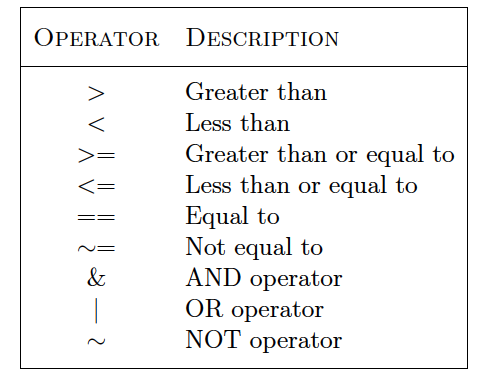

## **Exercise #3**

## The ``for...end'' loop

for variable = expression

    statements

end

**Examples:**

for i=1:5
    x=i*i
end

n=5;
out=n;
for i=n-1:-1:2
    out=out*i;
end
disp(out)

## The ``while...end'' loop

while expression

    statements

end

**Example:**

x = 1;
while x <= 10
    x = 3*x
end

## Switch

`switch` `switch_expression`

`   case ``case_expression`

      `statements`

`   case ``case_expression`

      `statements`

`    ...`

`   otherwise`

      `statements`

`end`

**Example:**

n = input('Enter a number: ');

switch n
    case -1
        disp('negative one')
    case 0
        disp('zero')
    case 1
        disp('positive one')
    otherwise
        disp('other value')
end

**Others: **

- The **break** statement**. **A while loop can be terminated with the break statement, which passes control to the first statement after the corresponding end. The break statement can also be used to exit a for loop.

- The **continue** statement can also be used to exit a for loop to pass immediately to the next iteration of the loop, skipping the remaining statements in the loop.

- Other control statements include **return**, etc..

## **Exercise #4**

# **Visualization of data**

## Figures, Axes and Graphs

-  A figure is a MATLAB window used for graphical display.

-  An axes is a 2D or 3D data space defined within a figure.

-  A plot is any graphic display you can create within a figure window. Figures can contain any number of plots and each plot is created within an axes.

-  A graph is a plot of data within an axes. Most plots are graphs.

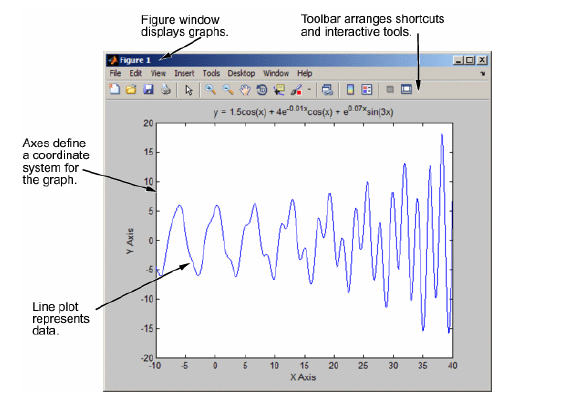

## Setting up figures

clear

figure

subplot(1,2,2)

x=-10:0.1:10
plot(cos(x))

subplot(1,2,1)

plot(sin(x))

close(1)

close all


Variables:

    Systolic: 100×1 double
        Values:

            min       109       
            median    122       
            max       138       

    Age: 100×1 double
        Values:

            min       25   
            median    39   
            max       50   

    Weight: 100×1 double
        Values:

            min         111   
            median    142.5   
            max         202   

    Gender: 100×1 cell array of character vectors

    Smoker: 100×1 logical
        Values:

            true     34      
            false    66      



## Axes and axis

axes()

ans =     mean_Systolic    mean_Age    mean_Weight
    _____________    ________    ___________

    122.78           38.28       154        


axes('Box','on','Color','r')

axis([0 0.5 0 0.8])

ans =     Fun_Systolic    Fun_Age    Fun_Weight
    ____________    _______    __________

    122.78          38.28      154       


## Objects, Handles and Properties

close all

ans =      Gender     GroupCount    mean_Systolic    mean_Age    mean_Weight    mean_Smoker
    ________    __________    _____________    ________    ___________    ___________

    'Female'    53            121.77           37.717      130.47         0.24528    
    'Male'      47            123.91           38.915      180.53         0.44681    


h1 = figure(1)

h2 = axes('Box','on','Color','y')

gcf % Get handles for the current figure

gca % Get handles for the current axis

get(gcf)

get(gca)

get(h1,'Resize')

set(gca,'Color','k')

## Plotting Functions

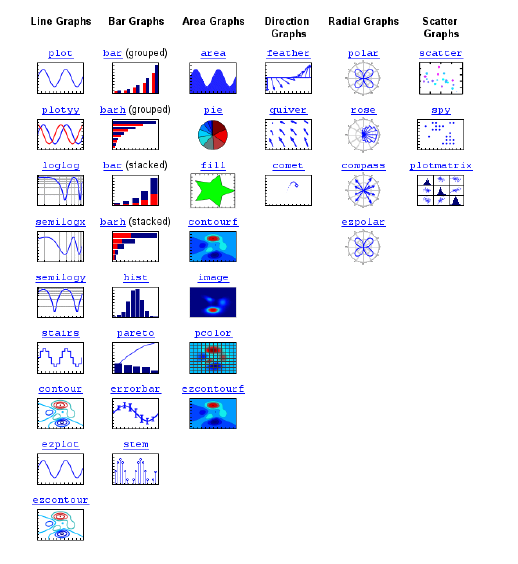

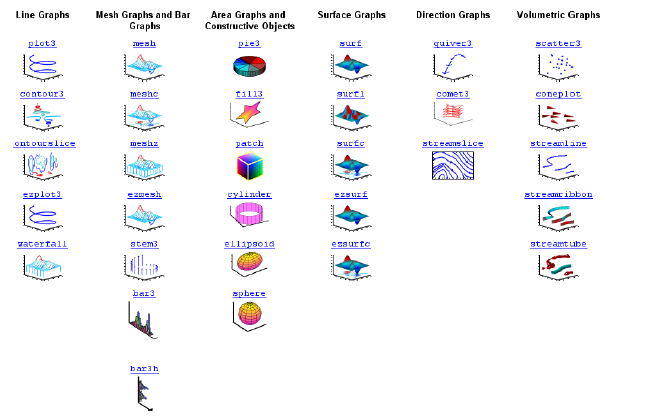

[http://www.mathworks.com/help/matlab/creating_plots/types-of-matlab-plots.html](http://www.mathworks.com/help/matlab/creating_plots/types-of-matlab-plots.html)

## Line Graphs: plot

The basic MATLAB graphing procedure, for example in 2D, is to take a vector of x-coordinates, x = (x1; ... ; xN), and a vector of y-coordinates, y = (y1; ... ; yN), locate the points (xi; yi), with i = 1; 2; ... ; n and then join them by straight lines. You need to prepare x and y in an identical array form; namely, x and y are both row arrays or column arrays of the same length.

clear
close all
figure(1)

x = 0:pi/10:2*pi;

y1 = 2*cos(x);

y2 = cos(x);

y3 = 0.5*cos(x);

plot(x,y1,'--rs',x,y2,'-gd',x,y3,':bo',...
       'LineWidth',2,...
       'MarkerEdgeColor','k',...
       'MarkerSize',10)

set(gca,'FontWeight','bold','FontSize',20)

xlabel('0 \leq x \leq 2\pi')

ylabel('Cosine functions')

legend('2*cos(x)','cos(x)','0.5*cos(x)')

title('Typical example of multiple plots')

axis([0 2*pi -3 3])

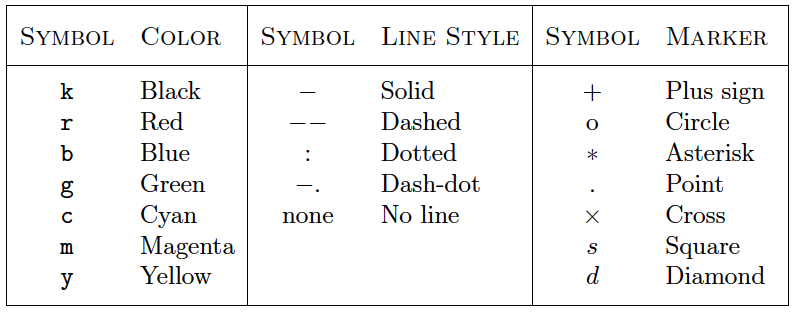

close all

A=[1:10;cos(1:10)]

plot(A)

plot(A')

## Bar Graphs

close all

bar(1:10)

subplot(3,1,1)

bar(magic(5))

subplot(3,1,2)

barh(magic(5))

subplot(3,1,3)

bar(magic(5),'stacked')

barh(magic(5),'stacked')

## **3D Example**

The function plot3 is the same as the plot function, but in three dimensions. In addition to this standard three dimensional plot, we can also create surfaces and contour plots.

clear
close all

x=linspace(-2,2);

y=linspace(-5,5);

[X,Y]= meshgrid(x,y);

Z=Y./(1+X.^2+Y.^2);

surf(X,Y,Z)

## **4D Example**

load accidents hwydata                         % load data

long = -hwydata(:,2);                              % longitude data

lat = hwydata(:,3);                                % latitude data

rural = 100 - hwydata(:,17);                       % percent rural data

fatalities = hwydata(:,11);                        % fatalities data

scatter3(long,lat,rural,40,fatalities,'filled')    % draw the scatter plot

set(gca,'FontWeight','bold','FontSize',20)
xlabel('W. Longitude')
ylabel('N. Latitude')
zlabel('% Rural Population')

cb = colorbar;                                     % create and label the colorbar

cb.Label.String = 'Fatalities per 100M vehicle-miles';